## **Lab 1 Part 1 Matlab for Regression**

### 1.1 Introduction 

- The objective of this task is to learn about designing and implementing basic machine learning algorithms for regression, with a focus on methods that are extensible to deep learning, i.e. linear regression with stochastic gradient descent for parameter estimation.

- One of the key aims of the lab is to show how the basic maths can be used to code an algorithm for machine learning, then how to use the deep learning tools to do the same thing, so that we gain insight into what the deep learning tools are doing.

- You will need the Deep Learning Toolbox installed.

- This lab is not assessed (but the exam contains questions relevant to the labs)

- For related background reading to this lab, you can check the Lecture 2 notes/slides on Blackboard and [Chapter 5](https://www.deeplearningbook.org/contents/ml.html) of the book Deep Learning (Goodfellow, Bengio and Courville, 2016).

- Work through all lab parts first, then do the quiz on Blackboard to check you have understood the material.

### 1.2 Define data

First, we set up some data to model, with input $x$ and output $y$, from a linear model with additive Gaussian noise, where


$$y=w_{1\;} x+w_0 +\textrm{noise}$$


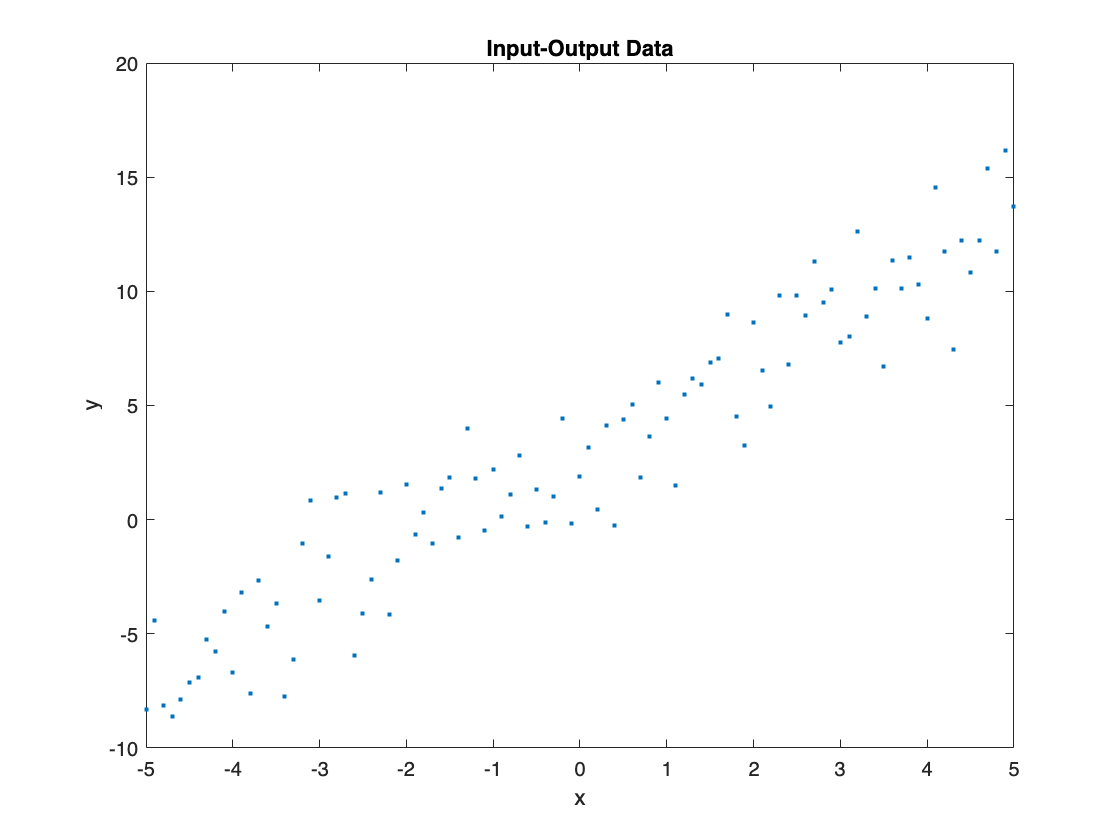

clear all

%% generate a data set from a linear model

% initialise the random number generator seed for repeatable results
rng(1,'twister');

% define linear function with additive noise y = w1*x + w0 + noise
w1 = 2;                 % linear function gradient parameter
w0 = 3;                 % linear function offset parameter
x = -5:0.1:5;           % input data samples
m = length(x);          % data length
noise = 2*randn(1,m);   % Gaussian noise
y = w1*x + w0 + noise;  % output
N = 2;                  % number of parameters

% create training data set
idx = randi([1 m],1,m);   % set of random indices
X = [ones(1,m); x];       % construct the regression matrix

figure;
plot(x,y,'.');
xlabel('x');
ylabel('y');
title('Input-Output Data')

Note: if the plot appears above that is fine, but if the plot appeaers to the right of the code and is tiny you need to change the view - click the middle, small button toward the top right of this window that says 'Output inline' when you hover the mouse over it.

### 1.3 Machine learning - train a linear regression model using SGD

The model we are trying to identify from data pairs $\left(x,y\right)$ is 


$$\hat{y} =w_{1\;} x+w_0$$


i.e. the model output is $\hat{y}$ and the parameters  $w_{1\;}$ and $w_0$ are unknown. We will use stochastic gradient descent to estimate the model parameters  $w_{1\;}$ and $w_0$. 

The loss function here is the sum-of-squared error, which for the case of a Gaussian likelihood is equivalent to the negative log-likelihood in maximum likelihood estimation (up to a scaling factor $1/2\sigma {\;}^2$, where $\sigma$ is the standard deviation of the Gaussian likelihood),


$$J\left(\theta \right)=\sum_j e_j^2 \;=-\sum_j \log \;p\left(y_j |x;\theta \;\right)\;$$


where $\theta ={\left(w_{0\;} ,w_{1\;} \right)}^T$ is the parameter vector for our linear model. Note that we derived this loss function in Lecture 2.

The SGD update for the parameters is


$$\theta \gets \theta -\epsilon \;g$$


where $\epsilon$ is the SGD learning rate and $g$ is the estimate of the loss function gradient. 

Note, in the code below, all the data is presented one at a time to the learning update rule, a minibatch size of 1, and the code loops through all the data once only - an epoch size of 1. Make sure you understand the distinction between a training iteration and a training epoch.

The SGD code for parameter estimation is below (this takes about 30 seconds to run):

%% parameter estimation using SGD

% initialise SGD algorithm parameters
epsilon = 0.2;                % learning rate
theta = zeros(N,1);            % initialise parameters
maxIter = m;                   % set number of training iterations
lossTrain = nan(maxIter,1);    % initialise loss function storage
thetaStore = nan(N,maxIter);   % initialise parameter storage

% loop over data samples
for j = 1:maxIter

    % model prediction using a single random data point
    yhat = theta'*X(:,idx(j));

    % estimate gradient of loss function
    g = (yhat-y(idx(j)))*X(:,idx(j));

    % SGD parameter estimation algorithm update
    theta = theta - epsilon*g;

    % store parameter values for analyis in the next part
    thetaStore(:,j) = theta;

end

Note the keys steps in the algorithm:

- Model prediction $\hat{y\;}$

- Loss function gradient estimate $g$

- Parameter update using SGD $\theta \gets \theta -\epsilon \;g$

### 1.4 Plot the output and evaluate results

Let's plot the output from the SGD learning algorithm to visualise and understand better what is going on - note that plotting the output is more complicated and longer than doing the actual machine learning. You will NOT be examined on plotting output!!

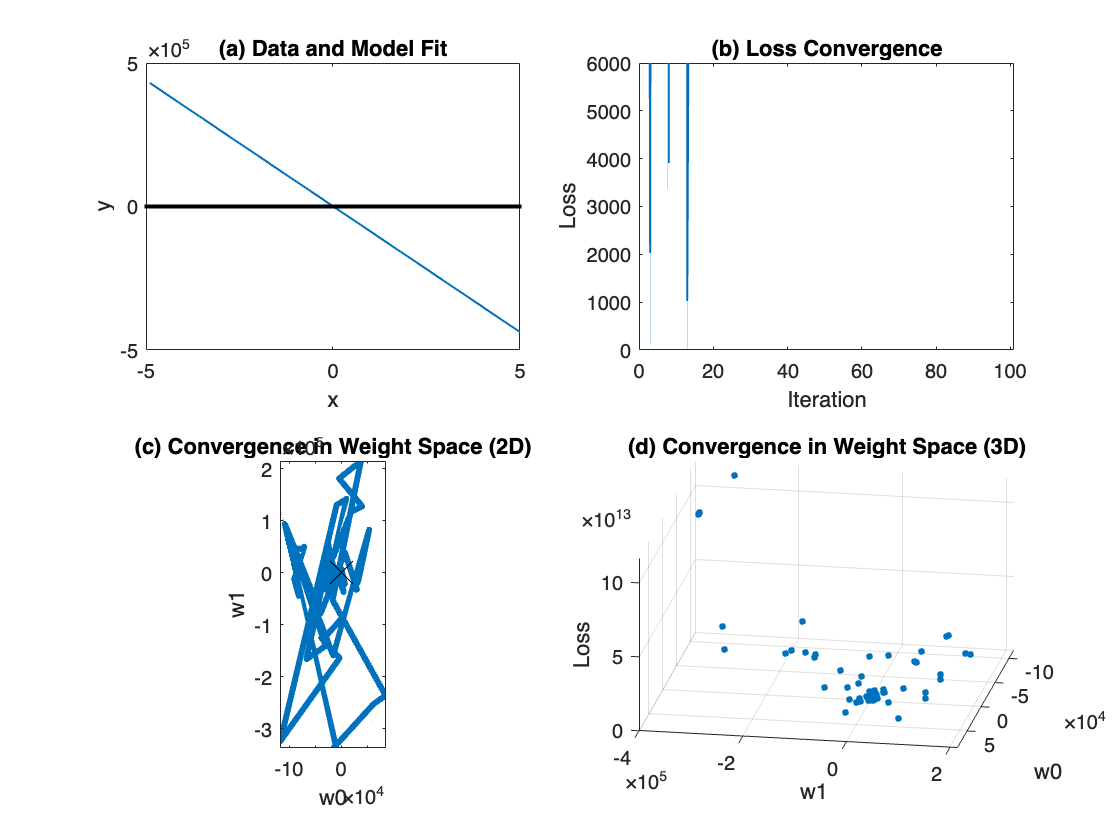

%% plot output

% evaluate loss function over grid of parameter values w1 and w0
w1vec = linspace(-1,5,300);      % vector of w1 values
w0vec = linspace(-1,5,200);      % vector of w0 values
Z = []; % initialise cost matrix
for ii = 1:length(w1vec)
    for jj = 1:length(w0vec)
        yhat = [w0vec(jj); w1vec(ii)]'*X(:,idx);
        Z(ii,jj) = sum((yhat - y(idx)).^2);
    end
end

% initialise figure
h1 = figure;
set(0,'DefaultLegendAutoUpdate','off'); % prevent auto-update of legend
cols = get(0, 'DefaultAxesColorOrder'); % define colours for plotting
subplot(2,2,4);
surf(w0vec,w1vec,Z,'edgecolor','none'); hold on; colormap(flipud(bone(256)));
view(100,30);
set(gcf,'color','w');

% plot results: loop over all parameter updates
for j = 1:maxIter

    % unpack parameter values
    theta = thetaStore(:,j);

    % loss function evaluation on training data
    yhat = theta'*X(:,idx);                   % model prediction
    lossTrain(j,1) = sum((yhat - y(idx)).^2); % loss

    % plot results
    figure(h1);
    % data and model fits
    subplot(2,2,1); cla;
    plot(x(idx),yhat,'linewidth',1); hold on;
    xlabel('x'); ylabel('y');
    plot(x,y,'.k');
    title('(a) Data and Model Fit')

    % convergence of the loss function over iterations
    subplot(2,2,2); cla
    plot(lossTrain,'linewidth',1);
    title('(b) Loss Convergence')
    xlim([0 maxIter]);
    ylim([0 6000])
    xlabel('Iteration'); ylabel('Loss');

    % 2D view of the convergence of the weights
    subplot(2,2,3); cla;
    contourf(w0vec,w1vec,Z); hold on; colormap(flipud(bone(256)));
    plot(thetaStore(1,1:j),thetaStore(2,1:j),'linewidth',3);
    plot(w0,w1,'kx','markersize',16)
    axis equal
    xlabel('w0'); ylabel('w1');
    title('(c) Convergence in Weight Space (2D)')

    % 3D view of the convergence of the weights
    subplot(2,2,4);
    plot3(theta(1),theta(2),lossTrain(j,1), ...
        '.','markersize',10,'color',cols(1,:));
    hold on
    xlabel('w0'); ylabel('w1');
    zlabel('Loss');
    title('(d) Convergence in Weight Space (3D)')
    drawnow;
end

Note in the plot above you can use the slider to manually scroll through the training iterations and use the play button to play through the iterations. Notice how the parameter estimates iterator toward the minimum in the loss function, marked by a cross in panel c.

### 1.5 Deep Learning Toolbox for Regression

We can do the same task as above but using the Deep Learning Toolbox instead. The advantage of using the toolbox is that it is more easily extended to complex tasks. But note, in this example it uses the same underlying methods that we developed above, including 

- a linear model, implemented as a fully connected layer

- minimisation of the mean-squared error (basically the same as sum-of-squared error but with normalisation of the sum-of-squared error term, which is somewhat irrevelant when using stochasic gradient descent because the normalisation term can be absorbed into the learning rate parameter epsilon that multiplies the gradient term)

- parameter estimation by stochastic gradient descent, implemented through the training option "sgdm"

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |         5.75 |         16.5 |          0.0010 |
|       5 |          50 |       00:00:04 |         3.22 |          5.2 |          0.0010 |
|      10 |         100 |       00:00:05 |         2.54 |          3.2 |          0.0010 |
|      15 |         150 |       00:00:05 |         2.38 |          2.8 |          0.0010 |
|      20 |         200 |       00:00:05 |         2.41 |          2.9 |          0.0010 |
|      25 |         250 |       00:00:06 |         2.46 |          3.0 |          0.0010 |
|      30 |         300 |       00:00:06 |         2.49 |         

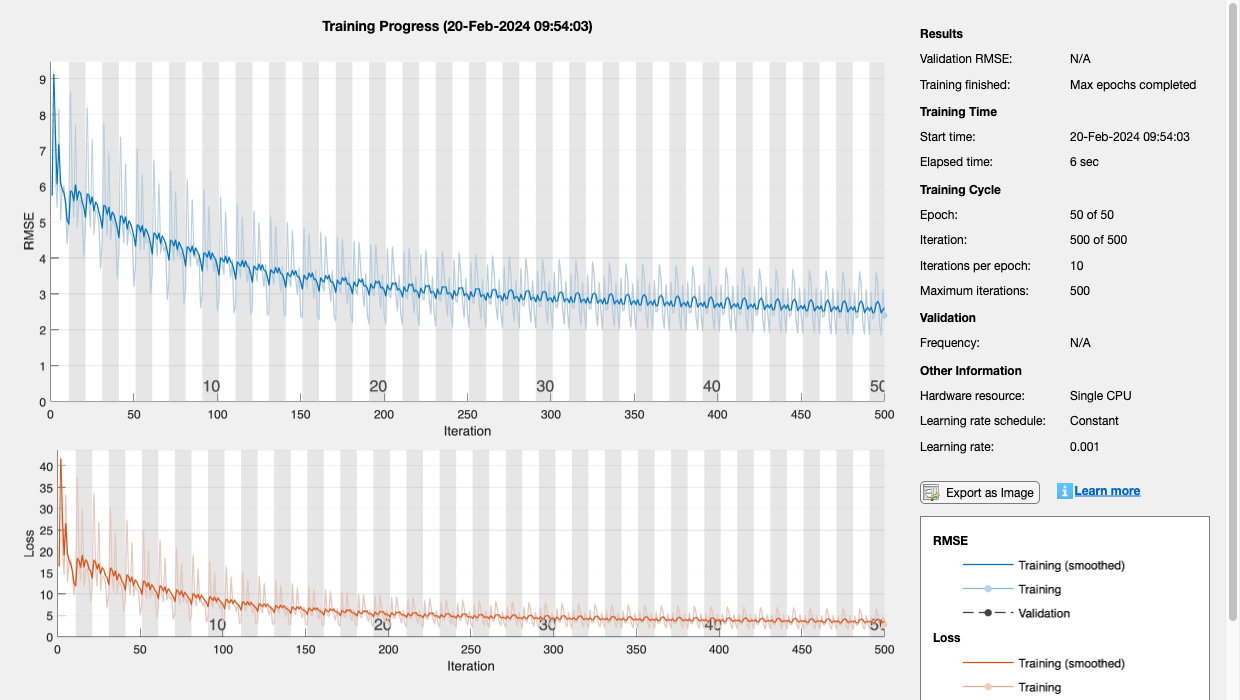

%% Setup and train a linear regression model using the deep learning toolbox

% define the deep feedforward network layers
layers = [featureInputLayer(1)   % input layer with 1 feature
    fullyConnectedLayer(1)       % fully connected, or linear layer
    regressionLayer];            % regression output layer

% analyze the network
analyzeNetwork(layers)

% Train network
% Specify the training options
options = trainingOptions("sgdm", ...  % select SGD as the optimization method
    "MiniBatchSize",10, ...             % define the minibatch size
    "MaxEpochs",50, ...                 % define the number of epochs
    "InitialLearnRate",0.001, ...       % define the learning rate epsilon
    "Verbose",true, ...                % show training output
    "Plots","training-progress", ...   % show convergence plots
    "Momentum",0);                     % turn off momentum (Lecture 4 material) 

% Train the network using the training data
net = trainNetwork(x',y',layers,options);

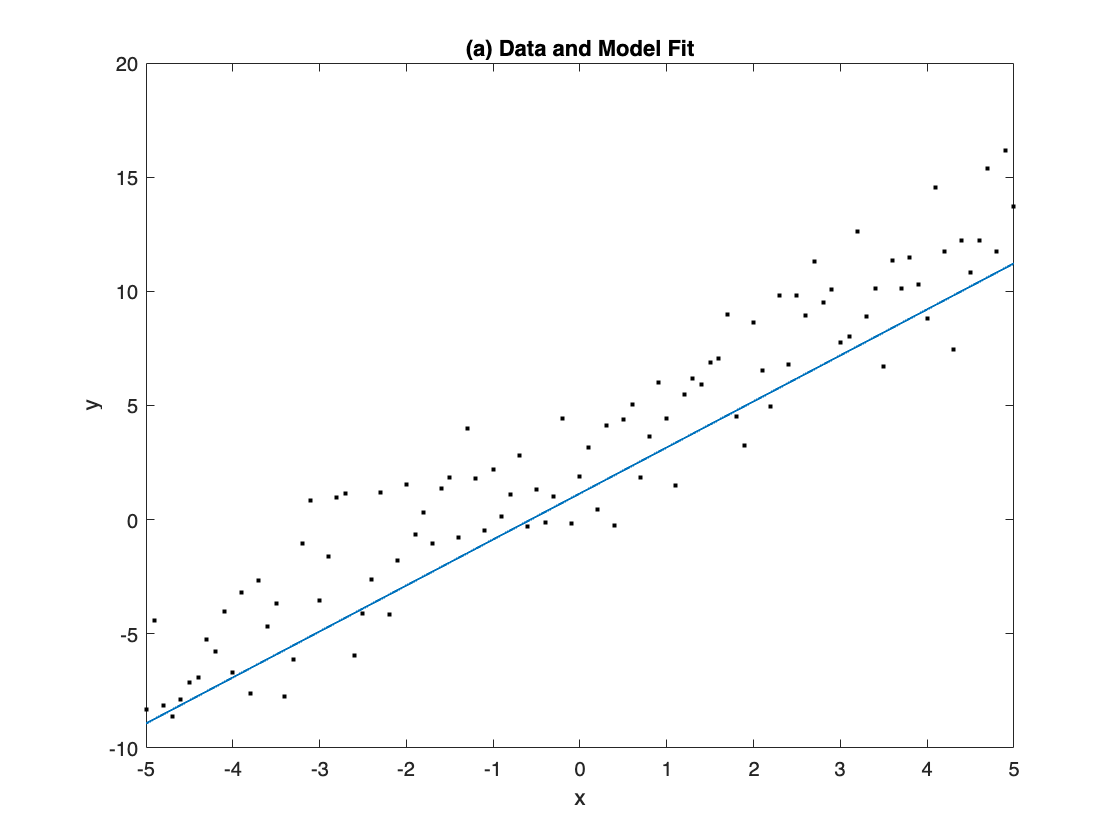

%% evaluate model 
yhat = predict(net,x');

% plot results
figure;
plot(x,yhat,'linewidth',1); hold on;
xlabel('x'); ylabel('y');
plot(x,y,'.k');
title('(a) Data and Model Fit')

So, hopefully you now see how easy it is to do either manual coding of the learning algorithm or to use the toolbox. And also you should now appreciate what the toolbox is doing when you setup the model and call functions like **trainNetwork**.

% End of Lab Part 1 - move onto next part